## **Lecture 6**

Matlab $Z_{\frac{\alpha \;}{2}}$=norminv$\left(1-\frac{\alpha }{2}\right)$. Man siger 1- foran at matlab integerer fra højre. Beregner altid hvor meget er der til venstre for mit interval.

$\mathrm{tinv}\left(1-\frac{\alpha }{2},n-1\;\right)$Benyt denne måde for at få midten af student-t fordelingen.

$\sigma^2 =s^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\bar{x} \right)}^2 \to$ s = var(x), x = [1, 7, 14 17]


$$\begin{array}{l}
\chi_{n-1,\frac{\alpha }{2}}^2 =\mathrm{chi2inv}\left(1-\frac{\alpha }{2}\;,n-1\right)\\
\chi_{n-1,1-\frac{\alpha }{2}}^2 =\mathrm{chi2inv}\left(\frac{\alpha }{2}\;,n-1\right)
\end{array}$$


format shortg

**8.1.3**

A random sample has been taken from a normal distribution and the following confidence intervals constructed using the same data: (38.02, 61.98) and (39.95, 60.05) 

a. What is the value of the sample mean?

%alternativ: a = mean([38.02 61.98])
a1 = (61.98+38.02)/2

a3 = 50

a1 = 50

a2 = (60.05+39.95)/2

a2 = 50

b. One of these intervals is a 95% CI and the other is a 90% CI. Which one is the 95% CI and why?

(38.02, 61.98) is 95%. This is because if the CI is higher, so there is a larger chance that the given value is between these two 

(39.95, 60.05) is 90%. Since the CI is lower, we have a smaller chance of getting value between the intervals.

**8.1.4**

A confidence interval estimate is desired for the gain in a circuit on a semiconductor device. Assume that gain is normally distributed with standard deviation σ = 20.

a. How large must n be if the length of the 95% CI is to be 40?

z_a = norminv(1-(0.05/2))

z_a = 1.9600


$$\begin{array}{l}
\mathrm{length}=2\cdot \frac{\sigma }{\sqrt{\;n}}\cdot Z_{\frac{\alpha }{2}} \\
\frac{1}{2}\cdot \;\mathrm{length}=\frac{\sigma }{\sqrt{\;n}}\cdot Z_{\frac{\alpha }{2}} \to \frac{1}{2}\cdot \;40=\frac{20}{\sqrt{\;n}}\cdot \;1\ldotp 96\to 20\sqrt{\;\left(n\right)}=20\cdot 1\ldotp 96\to \sqrt{\;n}=\frac{20\cdot 1\ldotp 96}{20}\to n=\left(\frac{20\cdot 1\ldotp 96}{20}\right)
\end{array}$$


n_a = ((20*1.96)/20)^2 

n_a = 3.8416

Round n up to 4.

b. How large must n be if the length of the 99% CI is to be 40?

z_b = norminv(1-(0.01/2))

z_b = 2.5758

n_b = ((20*2.5758)/20)^2 

n_b = 6.6347

Round n up to 7.

**8.1.12**

Ishikawa et al. [“Evaluation of Adhesiveness of Acinetobacter sp. Tol 5 to Abiotic Surfaces,” Journal of Bioscience and Bioengineering (Vol. 113(6), pp. 719–725)] studied the adhesion of various biofilms to solid surfaces for possible use in environmental technologies. Adhesion assay is conducted by measuring absorbance at A590. Suppose that for the bacterial strain Acinetobacter, five measurements gave readings of 2.69, 5.76, 2.67, 1.62, and 4.12 dyne-cm2. Assume that the standard deviation is known to be 0.66 dyne-cm2.

x = [2.69 5.76 2.67 1.62 4.12]

x =     2.6900    5.7600    2.6700    1.6200    4.1200


muHat = mean(x)

muHat = 3.3720

sigma = 0.66

sigma = 0.6600

n = length(x)

n = 5

z = norminv(1-(0.05/2))

z = 1.9600

a. Find a 95% confidence interval for the mean adhesion.

a_upper = muHat + (0.66/sqrt(n))*z  

a_upper = 3.9505

a_lower = muHat - (0.66/sqrt(n))*z

a_lower = 2.7935


$$2\ldotp 7935<\mu <3\ldotp 9505$$


b. If the scientists want the confidence interval to be no wider than 0.55 dyne-cm2, how many observations should they take?


$$0\ldotp 55=2\cdot \frac{\sigma }{\sqrt{\;n}}\cdot Z_{\frac{\alpha }{2}} \to 0\ldotp 55=\frac{2\cdot 0\ldotp 66\cdot 1\ldotp 96}{\sqrt{n}}\to n={\left(\frac{2\cdot 0\ldotp 66\cdot 1\ldotp 96}{0\ldotp 55}\right)}^2$$


n = ((2*0.66*1.96)/0.55)^2

n = 22.1276

Round up to 23

**8.2.1**

A random sample has been taken from a normal distribution. Output from a software package follows:

SE mean (Standard error mean)


$$\sigma_{\bar{x} } =\frac{\sigma }{\sqrt{n}}\;$$


n = 10;
sum = 251.848;
s = 1.605

s = 1.6050

a. Fill in the missing quantities.

variance = s^2

variance = 2.5760

mu = sum/n

mu = 25.1848

b. Find a 95% CI on the population mean.

t = tinv(1-(0.05/2),n-1)

t = 2.2622

b_upper = mu + ((s/sqrt(n))*t)

b_upper = 26.3329

b_lower = mu - ((s/sqrt(n))*t)

b_lower = 24.0367


$$24\ldotp 04<\mu <26\ldotp 33$$


clear

**8.2.9**

The compressive strength of concrete is being tested by a civil engineer who tests 12 specimens and obtains the following data:

2216  2237  2249  2204

2225  2301  2281  2263

2318  2255  2275  2295

x = [2216 2237 2249 2204 2225 2301 2281 2263 2318 2255 2275 2295]

x =         2216        2237        2249        2204        2225        2301        2281        2263        2318        2255        2275        2295


mu = mean(x);
s = std(x);
n = length(x);

a. Check the assumption that compressive strength is normally distributed. Include a graphical display in your answer.

pd = makedist('Normal', 'mu', mu,'sigma', s)

pd =   NormalDistribution

  Normal distribution
       mu = 2259.92
    sigma = 35.5693


figure
ax = axes;
qqplot(x, 1:100)
set(ax, 'YTick', [0, 10, 20, 30, 40, 50, 60, 70, 80, 90, 100], 'YLim', [0, 100]);
ytickformat(ax, 'percentage');
ax.YGrid = 'on'

ax =   Axes with properties:

             XLim: [2200 2320]
             YLim: [0 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.13 0.11 0.775 0.815]
            Units: 'normalized'

  Show all properties


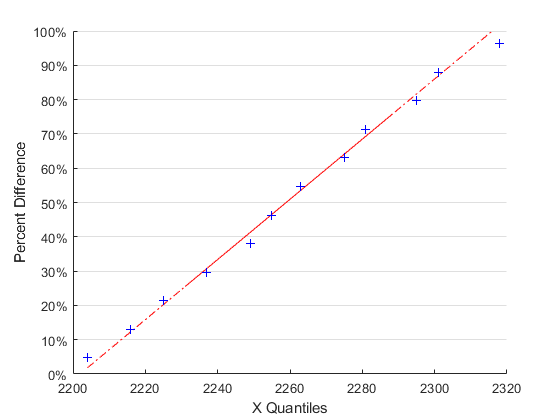

%xlabel('Patient');
ylabel('Percent Difference');

b. Construct a 95% two-sided confidence interval on the mean strength.


t = tinv(1-(0.05)/2, n -1);
b_upper = mu + ((s/sqrt(n))*t)

b_upper =        2282.5


b_lower = mu - ((s/sqrt(n))*t)

b_lower =        2237.3



$$2237\ldotp 3<\mu <2282\ldotp 5$$


c. Construct a 95% lower confidence bound on the mean strength. Compare this bound with the lower bound of the two-sided confidence interval and discuss why they are different.

t = tinv(1-(0.05), n -1);
c_lower = mu - ((s/sqrt(n))*t)

c_lower =        2241.5



$$\mu >2241\ldotp 5$$


Instead of have a 95% CI between both the top and bottom, we only have the alpha value in the lower bound. So the entire alpha value in on the left side of the distrubution.

**8.2.12**

A healthcare provider monitors the number of CAT scans performed each month in each of its clinics. The most recent year of data for a particular clinic follows (the reported variable is the number of CAT scans each month expressed as the number of CAT scans per thousand members of the health plan):

2.31, 2.09, 2.36, 1.95, 1.98, 2.25, 2.16, 2.07, 1.88, 1.94, 1.97, 2.02

x = [2.31 2.09 2.36 1.95 1.98 2.25 2.16 2.07 1.88 1.94 1.97 2.02];
mu = mean(x)

mu =        2.0817


s = std(x)

s =       0.15637


n = length(x);

a. Find a 95% two-sided CI on the mean number of CAT scans performed each month at this clinic.

t = tinv(1-(0.05)/2, n -1);
a_upper = mu + ((s/sqrt(n))*t)

b_upper =         2.181


a_lower = mu - ((s/sqrt(n))*t)

b_lower =        1.9823



$$1\ldotp 9823<\mu <2\ldotp 181$$


b. Historically, the mean number of scans performed by all clinics in the system has been 1.95. Is there any evidence that this particular clinic performs more CAT scans on average than the overall system average?

Since $\mu =2\ldotp 0817$ it is higher than the 1.95 average. This is evidence that the clinic performs more CAT scans.

**8.3.3**

An article in Urban Ecosystems [“Urbanization and Warming of Phoenix (Arizona, USA): Impacts, Feedbacks and Mitigation” (2002, Vol. 6, pp. 183–203)] mentions that Phoenix is ideal to study the effects of an urban heat island because it has grown from a population of 300,000 to approximately 3 million over the last 50 years, which is a period with a continuous, detailed climate record. The 50-year averages of the mean annual temperatures at eight sites in Phoenix follow. Check the assumption of normality in the population with a probability plot. 

Construct a 95% confidence interval for the standard deviation over the sites of the mean annual temperatures.

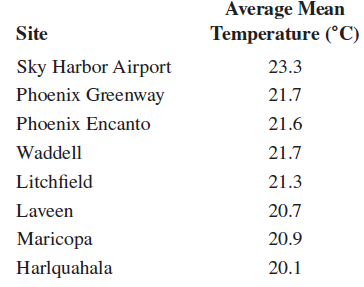

x = [23.3 21.7 21.6 21.7 21.3 20.7 20.9 20.1];
mu = mean(x);
s = std(x);
n = length(x);
ci_up = chi2inv(1-(0.05/2), n-1);
ci_low = chi2inv((0.05/2), n-1);


$$\begin{array}{l}
\chi_{n-1,\frac{\alpha }{2}}^2 =\mathrm{chi2inv}\left(1-\frac{\alpha }{2}\;,n-1\right)\\
\chi_{n-1,1-\frac{\alpha }{2}}^2 =\mathrm{chi2inv}\left(\frac{\alpha }{2}\;,n-1\right)
\end{array}$$



$$P\left(\frac{\left(n-1\right)s^2 }{{\chi^2 }_{n-1,\frac{\alpha }{2}\;\;} },\sigma^2 ,\frac{\left(n-1\right)s^2 }{{\chi^2 }_{n-1,1-\frac{\alpha }{2}\;\;} }\;\right)=1-\alpha \;$$



$$\begin{array}{l}
\frac{7\cdot \;{0\ldotp 94}^2 }{16\ldotp 013}\le \sigma^2 \le \frac{7\cdot \;{0\ldotp 94}^2 }{1\ldotp 6899}\\
0\ldotp 38626\le \sigma^2 \le 3\ldotp 6601\\
0\ldotp 6215\le \sigma \;\le 1\ldotp 9131
\end{array}$$


**8.4.1**

The 2004 presidential election exit polls from the critical state of Ohio provided the following results. The exit polls had 2020 respondents, 768 of whom were college graduates. Of the college graduates, 412 voted for George Bush.


$$\hat{p} -Z_{\frac{\alpha }{2}} \sqrt{\;\frac{\hat{p} \left(1-\hat{p} \right)}{n}}\le p\le \hat{p} +Z_{\frac{\alpha }{2}} \sqrt{\;\frac{\hat{p} \left(1-\hat{p} \right)}{n}}$$


respondents = 2020;
colstud=768; % n
bushVotes = 412;

a. Calculate a 95% confidence interval for the proportion of college graduates in Ohio who voted for George Bush.

mu = bushVotes/colstud % this is also pHat

mu =       0.53646


z = norminv(1-0.05/2);

a_upper = mu + z*sqrt((mu*(1-mu))/colstud)

a_upper =       0.57173


a_lower = mu - z*sqrt((mu*(1-mu))/colstud)

a_lower =       0.50119



$$0\ldotp 50119\le p\le 0\ldotp 57173$$


b. Calculate a 95% lower confidence bound for the proportion of college graduates in Ohio who voted for George Bush.

z = norminv(1-0.05);
b_lower = mu - z*sqrt((mu*(1-mu))/colstud)

b_lower =       0.50686



$$p>0\ldotp 50686$$
